# Textbook: Applied Nonlinear Control, Slotine, Li, 1991

# EXERCISE 5.6 - SATURATION OSCILLATOR

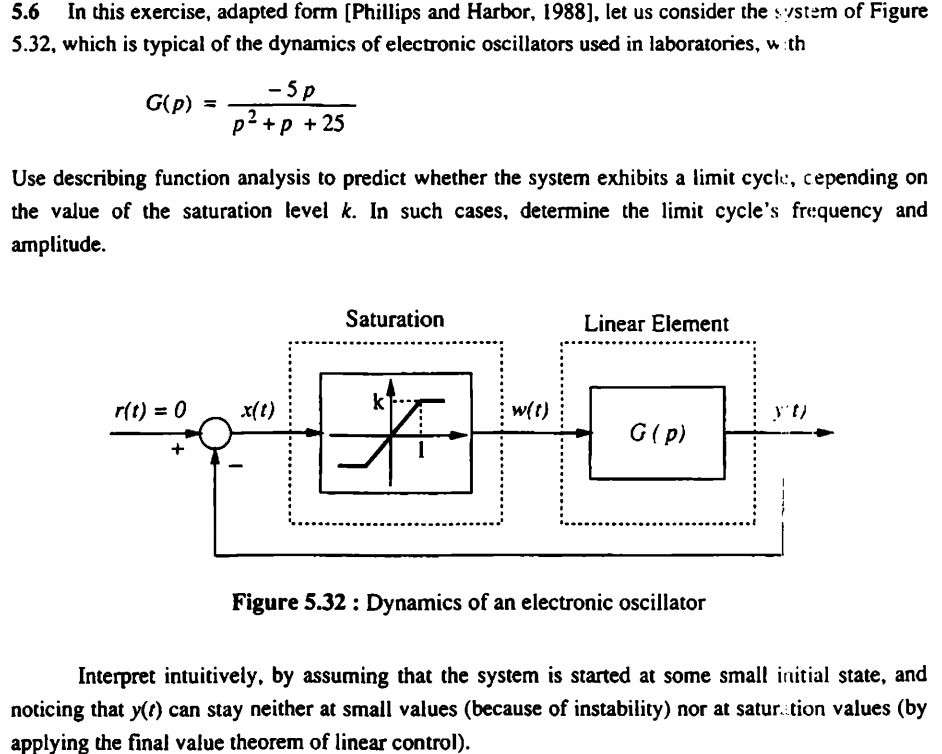

# Solution:

Describing Function Analysis

System:

r(t) = 0

Linear element:

Saturation characteristic:

w = k*x for `x` <= 1 w = k*sign(x) for `x` > 1

Therefore, k is the saturation output level and the breakpoint is `x` = 1.

This script determines: 1. whether a limit cycle exists, 2. its frequency, 3. its amplitude, 4. its stability, using the describing function technique.

clear;
clc;
close all;

## 1. Saturation Level

Change k to study different cases.

Examples:

     k < 0.2  : no limit cycle

    k = 0.2  : marginal case

    k > 0.2  : stable limit cycle


k = 1;

## 2. Linear Element

num = [-5 0];
den = [1 1 25];

Gs = tf(num,den);

## 3. Describing Function of the Saturation

For a sinusoidal input:

    x(t) = A*sin(w*t)

If A <= 1, the saturation does not become active:

    N(A) = k

If A > 1:

                  2k                        1              1

    N(A) = ------ [ asin(1/A) + --- sqrt(1 - ---    ) ]

                   pi                        A             A^2

The saturation is memoryless, so N(A) is real and does not depend on w.

## 4. Limit-Cycle Condition

The describing-function condition is:

    G(jw)*N(A) = -1

Since N(A) is real and positive, G(jw) must be negative real.

 For

                  -5jw

     G(jw) = ------------------

              25-w^2 + jw

     imag(G(jw)) = 0 gives:

     w = 5 rad/s

 At w = 5 rad/s:

     G(j5) = -5

 Therefore:

     (-5)*N(A) = -1

     N(A) = 0.2


w_limit = 5;
N_required = 1/5;

## 5. Decide Whether a Limit Cycle Exists

fprintf('\nEXERCISE 5.6 - DESCRIBING FUNCTION ANALYSIS\n');


EXERCISE 5.6 - DESCRIBING FUNCTION ANALYSIS


fprintf('--------------------------------------------\n');

--------------------------------------------


fprintf('Saturation level k = %.4f\n',k);

Saturation level k = 1.0000


fprintf('Required describing-function value = %.4f\n\n',N_required);

Required describing-function value = 0.2000




if k < N_required

    fprintf('k < 0.2\n');
    fprintf('Since N(A) <= k < 0.2 for every amplitude,\n');
    fprintf('G(jw)N(A) cannot reach -1.\n\n');
    fprintf('RESULT: NO LIMIT CYCLE is predicted.\n');
    fprintf('The small-signal closed-loop system is stable.\n\n');

    limit_cycle_exists = false;
    marginal_case = false;
    A_limit = NaN;

elseif abs(k-N_required) < 1e-10

    fprintf('k = 0.2\n');
    fprintf('For A <= 1, N(A) = 0.2 exactly.\n');
    fprintf('The small-signal closed-loop poles are on the imaginary axis.\n\n');
    fprintf('RESULT: This is a MARGINAL CASE.\n');
    fprintf('There is no unique isolated limit cycle predicted by the describing function.\n\n');

    limit_cycle_exists = false;
    marginal_case = true;
    A_limit = NaN;

else

    fprintf('k > 0.2\n');
    fprintf('A limit cycle is predicted.\n\n');

    limit_cycle_exists = true;
    marginal_case = false;

k > 0.2


A limit cycle is predicted.



## 6. Find the Limit-Cycle Amplitude

 For A > 1:

N(A) = 0.2

Solve this equation numerically.


    Nfun = @(A) (2*k/pi)*(asin(1./A) + (1./A).*sqrt(1 - 1./A.^2));

    equation = @(A) Nfun(A) - N_required;

    % Find an upper bound where the function changes sign.
    A_high = 2;

    while equation(A_high) > 0
        A_high = 2*A_high;
    end

    % Solve for the amplitude.
    A_limit = fzero(equation,[1+1e-6 A_high]);

## 7. Display Limit-Cycle Result

    fprintf('LIMIT CYCLE PREDICTION\n');
    fprintf('Amplitude A = %.4f\n',A_limit);
    fprintf('Angular frequency w = %.4f rad/s\n',w_limit);
    fprintf('Frequency f = %.4f Hz\n',w_limit/(2*pi));
    fprintf('Period T = %.4f s\n\n',2*pi/w_limit);

end

LIMIT CYCLE PREDICTION


Amplitude A = 6.3397


Angular frequency w = 5.0000 rad/s


Frequency f = 0.7958 Hz


Period T = 1.2566 s



## 8. Nyquist Plot: G(jw) and -1/N(A)

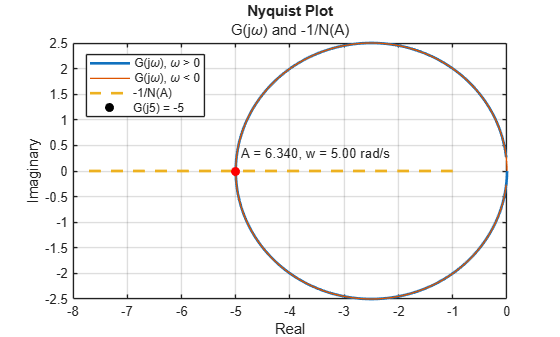

w = linspace(0.01,20,4000);

s = 1i*w;

Gjw = (-5*s)./(s.^2 + s + 25);

% Amplitude vector for the describing-function curve.
if limit_cycle_exists
    Amax = max(10,1.5*A_limit);
else
    Amax = 10;
end

A = linspace(0.05,Amax,1500);

N = zeros(size(A));

for i = 1:length(A)

    if A(i) <= 1

        N(i) = k;

    else

        N(i) = (2*k/pi)*(asin(1/A(i)) + (1/A(i))*sqrt(1 - 1/A(i)^2));

    end

end

minus_inv_N = -1./N;

figure('Name','Exercise 5.6 - Describing Function', 'NumberTitle','off');

% Positive-frequency Nyquist branch.
plot(real(Gjw),imag(Gjw),'LineWidth',2);
hold on;

% Negative-frequency branch.
plot(real(Gjw),-imag(Gjw),'LineWidth',1);

% -1/N(A) lies on the negative real axis.
plot(minus_inv_N,zeros(size(minus_inv_N)),'--','LineWidth',2);

% Important point of the linear element.
plot(-5,0,'ko','MarkerFaceColor','k');

% Important point of the linear element.
plot(-5,0,'ko','MarkerFaceColor','k');

if limit_cycle_exists

    % Limit cycle point
    plot(-5,0,'ro','MarkerFaceColor','r');

    % Show amplitude and frequency near the intersection point
    text(-5 + 0.1, 0.35, sprintf('A = %.3f, w = %.2f rad/s',A_limit,w_limit));

end

grid on;
xlabel('Real');
ylabel('Imaginary');
title('Nyquist Plot');
subtitle('G(j\omega) and -1/N(A)');

legend('G(j\omega), \omega > 0', 'G(j\omega), \omega < 0', '-1/N(A)', 'G(j5) = -5', 'Location','best');

## 9. Plot G(jw)N(A) for Different Amplitudes

If limit cycle exists:

    Choose amplitudes below, at, and above the predicted limit cycle.

else:

    Example amplitudes when there is no unique limit cycle.



figure('Name','Exercise 5.6 - Limit Cycle Detection', 'NumberTitle','off');

hold on;

if limit_cycle_exists

    A_values = [1, 0.75*A_limit, A_limit, 1.25*A_limit];

else
  
    A_values = [0.5 1 2 5];

end

legend_text = cell(1,length(A_values)+1);

for m = 1:length(A_values)

    A0 = A_values(m);

    if A0 <= 1

        N0 = k;

    else

        N0 = (2*k/pi)*(asin(1/A0) + (1/A0)*sqrt(1 - 1/A0^2));

    end

    L = Gjw*N0;

    plot(real(L),imag(L),'LineWidth',1.5);

    legend_text{m} = sprintf('A = %.3f', A0);

end


Critical point

plot(-1,0,'ko','MarkerFaceColor','k');
legend_text{end} = '(-1,0)';

Show limit cycle frequency near the critical point

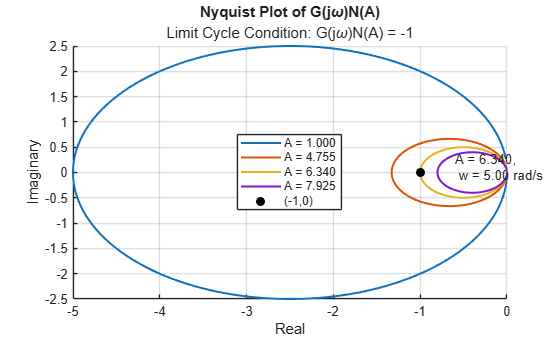


if limit_cycle_exists
    text(-1 + 0.4, 0.1, sprintf('A = %.3f,\n w = %.2f rad/s',A_limit,w_limit));
end

grid on;
xlabel('Real');
ylabel('Imaginary');
title('Nyquist Plot of G(j\omega)N(A)');
subtitle('Limit Cycle Condition: G(j\omega)N(A) = -1');

legend(legend_text,'Location','best');

## 10. Stability of the Predicted Limit Cycle

If Limit Cycle exists:

The equivalent closed-loop characteristic equation is:

    s^2 + (1 - 5*N(A))*s + 25 = 0

Therefore:

effective damping coefficient = 1 - 5*N(A)

Below the limit-cycle amplitude:

    N(A) > 0.2  -> damping < 0 -> amplitude grows.

Above the limit-cycle amplitude:

    N(A) < 0.2  -> damping > 0 -> amplitude decreases.

Hence the limit cycle is stable.


if limit_cycle_exists

    dA = 0.1*A_limit;

    A_low = max(1+1e-6,A_limit-dA);
    A_high = A_limit+dA;

    N_low = Nfun(A_low);
    N_high = Nfun(A_high);

    damping_low = 1 - 5*N_low;
    damping_high = 1 - 5*N_high;

    fprintf('LIMIT CYCLE STABILITY\n');
    fprintf('---------------------\n');

    fprintf('Below the limit cycle:\n');
    fprintf('A = %.4f\n',A_low);
    fprintf('N(A) = %.4f\n',N_low);
    fprintf('1 - 5N(A) = %.4f\n',damping_low);

    if damping_low < 0
        fprintf('Amplitude increases toward the limit cycle.\n\n');
    else
        fprintf('Amplitude does not increase toward the limit cycle.\n\n');
    end

    fprintf('Above the limit cycle:\n');
    fprintf('A = %.4f\n',A_high);
    fprintf('N(A) = %.4f\n',N_high);
    fprintf('1 - 5N(A) = %.4f\n',damping_high);

    if damping_high > 0
        fprintf('Amplitude decreases toward the limit cycle.\n\n');
    else
        fprintf('Amplitude does not decrease toward the limit cycle.\n\n');
    end

    if damping_low < 0 && damping_high > 0
        fprintf('Therefore, the predicted limit cycle is STABLE.\n\n');
    else
        fprintf('The stability test is inconclusive.\n\n');
    end

end

LIMIT CYCLE STABILITY


---------------------


Below the limit cycle:


A = 5.7057


N(A) = 0.2220


1 - 5N(A) = -0.1100


Amplitude increases toward the limit cycle.



Above the limit cycle:


A = 6.9737


N(A) = 0.1820


1 - 5N(A) = 0.0902


Amplitude decreases toward the limit cycle.



Therefore, the predicted limit cycle is STABLE.



## 11. Final Analytical Result

fprintf('FINAL RESULT\n');

FINAL RESULT


fprintf('------------\n');

------------


fprintf('k < 0.2 : no limit cycle is predicted.\n');

k < 0.2 : no limit cycle is predicted.


fprintf('k = 0.2 : marginal case; no unique isolated limit cycle.\n');

k = 0.2 : marginal case; no unique isolated limit cycle.


fprintf('k > 0.2 : stable limit cycle is predicted.\n');

k > 0.2 : stable limit cycle is predicted.


fprintf('          w = 5 rad/s.\n');

          w = 5 rad/s.


fprintf('          A is found from N(A) = 0.2.\n');

          A is found from N(A) = 0.2.



if limit_cycle_exists
    fprintf('For k = %.4f, A = %.4f.\n',k,A_limit);
end

For k = 1.0000, A = 6.3397.
